clear all
R = 1

R = 1

L = 1

L = 1

C = 1

C = 1

p = roots( [L*C R*C 1] )

p =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


% Vetor de tempo
t = 0:1e-2:20;

% raízes complexas conjugadas:
% alpha = -0.5 (parte real)
% beta =  0.866

alpha = real( p(1) )

alpha = -0.5000

beta = abs( imag( p(1) ) )

beta = 0.8660


% Interpretando as condições iniciais
% I0 : corrente no instante t=0
%      i(0) == I0
% V0: tensão sobre o capacitor em t=0
% Aplicando a LKT: Vr+Vl+Vc=0
% R*i(t) + L*di(t)/dt + Vc(t) = 0
% R*I0 + L*di(0)/dt + V0 = 0
% di(0)/dt = -(R*I0+V0)/L

% Admitindo V0=-10 e I0=0
% i(0)     = 0
% di(0)/dt = 10/L = 10



% condições de contorno:
% i(t) = exp(alpha*t) * (K1*cos(beta*t)+K2*sin(beta*t))
% i(0) = exp(alpha*0) * (K1*cos(0)+K2*sin(0)) = 0
% i(0) = K1 = 0
% Logo: K1 = 0
% i(t) = exp(alpha*t) * K2*sin(beta*t)
% di(t)/dt = alpha*exp(alpha*t) * K2*sin(beta*t) + exp(alpha*t) * beta*K2*cos(beta*t)
% di(0)/dt = alpha*exp(0) * K2*sin(0) + exp(0) * beta*K2*cos(0)
% di(0)/dt = beta*K2 = 10
% Logo: K2 = 10/beta

K1 = 0

K1 = 0

K2 = 10/beta

K2 = 11.5470

i = exp(alpha*t) .* (K1*cos(beta*t)+K2*sin(beta*t))

i =          0    0.0995    0.1980    0.2955    0.3920    0.4875    0.5820    0.6755    0.7680    0.8595    0.9500    1.0396    1.1281    1.2156    1.3022    1.3877    1.4723    1.5558    1.6384    1.7200    1.8006    1.8803    1.9589    2.0366    2.1133    2.1890    2.2638    2.3376    2.4104    2.4823    2.5532    2.6231    2.6921    2.7601    2.8272    2.8933    2.9585    3.0227    3.0860    3.1484    3.2098    3.2703    3.3299    3.3885    3.4462    3.5031    3.5589    3.6139    3.6680    3.7212


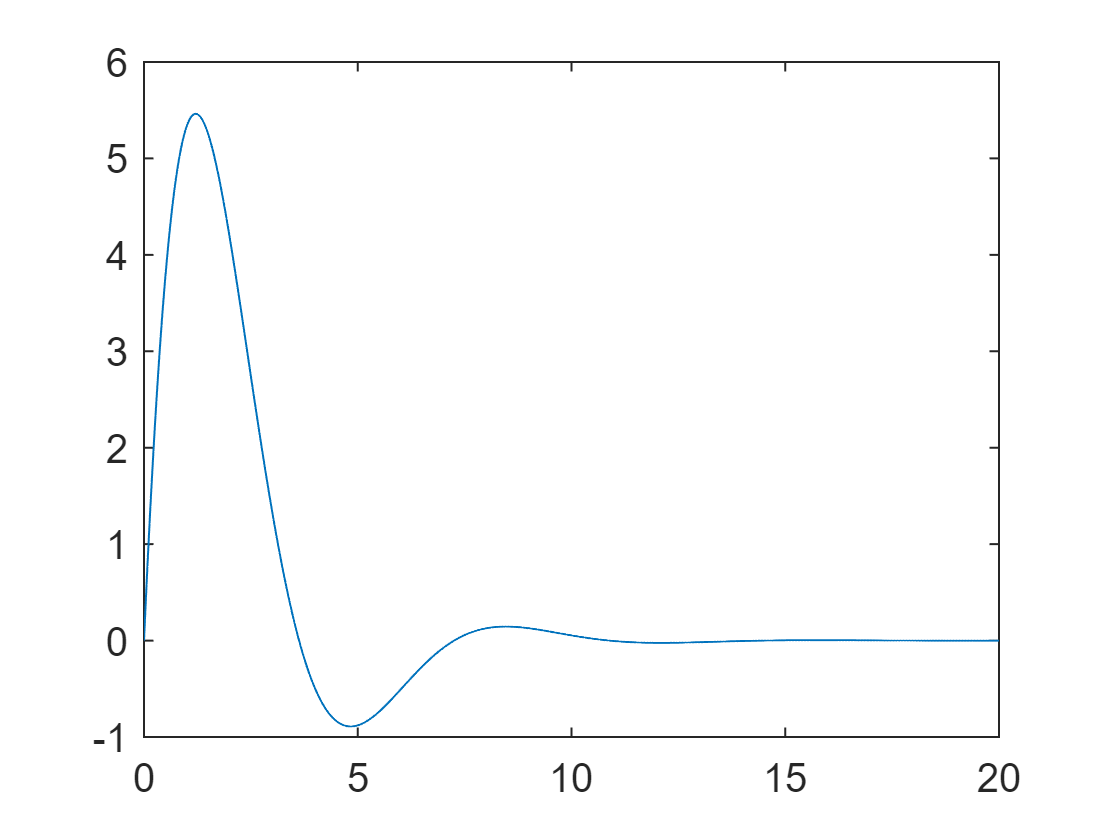

plot(t,i)